clear all
sympref('FloatingPointOutput', false)

ans = logical
   0


## Problem 2

### Part A

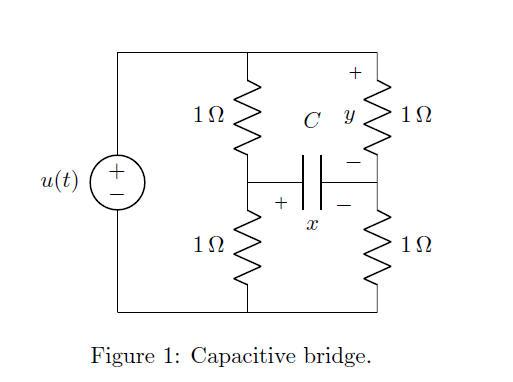

syms i_1 i_2 i_3 u x x_dot y C
%Loop 1 equation
l1eqn = i_1 + i_2 == u

$$l1eqn = i_{1}+i_{2}=u$$


%Node 1 equation
n1eqn = i_1 - i_2 == C*x_dot

$$n1eqn = i_{1}-i_{2}=C\,\dot{x}$$


%Loop 2 equation
l2eqn = -i_1 + y - x == 0

$$l2eqn = -x+y-i_{1}=0$$


%Node 2 equation
n2eqn = -y + i_3 == C*x_dot

$$n2eqn = -y+i_{3}=C\,\dot{x}$$


%Loop 2 equation
l3eqn = -i_2 + x + i_3 == 0

$$l3eqn = x-i_{2}+i_{3}=0$$


eqns = [l1eqn;n1eqn;l2eqn;n2eqn;l3eqn]

$$eqns = \left[\begin{array}{c} i_{1}+i_{2}=u\\ i_{1}-i_{2}=C\,\dot{x}\\ -x+y-i_{1}=0\\ -y+i_{3}=C\,\dot{x}\\ x-i_{2}+i_{3}=0 \end{array}\right]$$

state_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 y]);
state_eqn = isolate(state_eqn, x_dot)

$$state\_eqn = \dot{x}=-\frac{x}{C}$$

output_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 x_dot])

$$output\_eqn = 0=x-2\,y+u$$

output_eqn = isolate(output_eqn, y)

$$output\_eqn = y=\frac{x}{2}+\frac{u}{2}$$

### Part B

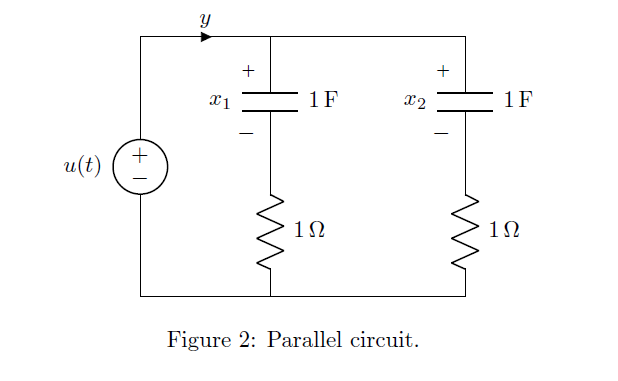

syms x_1 x_2 x_dot_1 x_dot_2 

%Loop 1 equation
l1eqn = x_1 + i_1 - u == 0

$$l1eqn = x_{1}-u+i_{1}=0$$


%Loop 2 equation
l2eqn = x_2 + i_2 - u == 0

$$l2eqn = x_{2}-u+i_{2}=0$$


%Node 1 equation
n1eqn = y == x_dot_1 + x_dot_2

$$n1eqn = y={\dot{x}}_{1}+{\dot{x}}_{2}$$


%Node 2 equation
n2eqn = i_1 == x_dot_1

$$n2eqn = i_{1}={\dot{x}}_{1}$$


%Node 3 equation
n3eqn = i_2 == x_dot_2

$$n3eqn = i_{2}={\dot{x}}_{2}$$


eqns = [l1eqn;l2eqn;n1eqn;n2eqn;n3eqn]

$$eqns = \left[\begin{array}{c} x_{1}-u+i_{1}=0\\ x_{2}-u+i_{2}=0\\ y={\dot{x}}_{1}+{\dot{x}}_{2}\\ i_{1}={\dot{x}}_{1}\\ i_{2}={\dot{x}}_{2} \end{array}\right]$$

solved_state_eqns = eliminate(eqns, [i_1 i_2 y])

$$solved\_state\_eqns = \left[-x_{2}-{\dot{x}}_{2}+u,x_{1}-x_{2}+{\dot{x}}_{1}-{\dot{x}}_{2}\right]$$

solved_state_eqns = [0;0] == [solved_state_eqns(1);solved_state_eqns(2)];
solved_state_eqns = [solved_state_eqns(1)-solved_state_eqns(2);solved_state_eqns(1)];
solved_state_eqns = [isolate(solved_state_eqns(1), x_dot_1);isolate(solved_state_eqns(2), x_dot_2)]

$$solved\_state\_eqns = \left[\begin{array}{c} {\dot{x}}_{1}=-x_{1}+u\\ {\dot{x}}_{2}=-x_{2}+u \end{array}\right]$$

solved_output_eqn = 0 == eliminate(eqns, [i_1 i_2 x_dot_1 x_dot_2]);
solved_output_eqn = isolate(solved_output_eqn, y)

$$solved\_output\_eqn = y=-x_{1}-x_{2}+2\,u$$

## Problem 3 

### Part A

State space model of spring mass system:

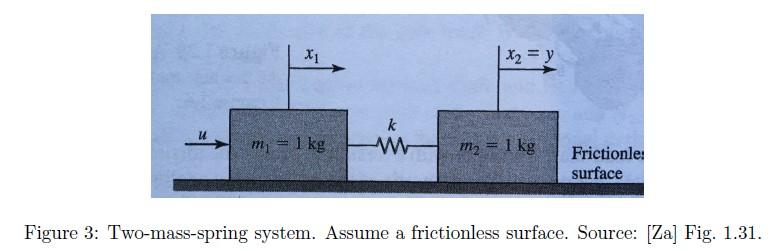

m1 = 1;
m2 = 1;
k = 1;

A = [0      0   1  0
        0      0   0  1
      -k/m1  k/m1  0  0
       k/m2 -k/m2  0  0];

B = [ 0
      0 
     1/m1
      0 ];

C = [ 0 1 0 0];

D = 0;

sys = ss(A,B,C,D);

eig(A)

ans =   -0.0000 + 1.4142i
  -0.0000 - 1.4142i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


Controllabilitry Gramian

syms Tau t


c_integrand = exp(A*Tau)*(B*B.')*exp(A.'*Tau)

$$c\_integrand = \left[\begin{array}{cccc} {\mathrm{e}}^{2\,Τ} & {\mathrm{e}}^{Τ} & {\mathrm{e}}^{Τ} & {\mathrm{e}}^{Τ}\\ {\mathrm{e}}^{Τ} & 1 & 1 & 1\\ {\mathrm{e}}^{Τ} & 1 & 1 & 1\\ {\mathrm{e}}^{Τ} & 1 & 1 & 1 \end{array}\right]$$

c_gram(t) = int(c_integrand,Tau, 0, t)

$$c\_gram(t) = \left[\begin{array}{cccc} \frac{{\mathrm{e}}^{2\,t}}{2}-\frac{1}{2} & {\mathrm{e}}^{t}-1 & {\mathrm{e}}^{t}-1 & {\mathrm{e}}^{t}-1\\ {\mathrm{e}}^{t}-1 & t & t & t\\ {\mathrm{e}}^{t}-1 & t & t & t\\ {\mathrm{e}}^{t}-1 & t & t & t \end{array}\right]$$

det_c_gram = det(c_gram)

$$det\_c\_gram(t) = 0$$

Evaluate $W_t$ at the time values $t_1 = 10 , ~t_2 = 20, ~ and~t_3 = 100$ seconds and find the eigenvalues and eigenvectors


t1 = 10;
t2 = 20;
t3 = 100;

%t1 = 10 
% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V1, D1] = eig(double(c_gram(t1)));
%Make sure they are ordered from largest to smallest
[d1,ind1] = sort(diag(D1), 'descend');
Ds1 = D1(ind1,ind1);
Vs1 = V1(:,ind1);

%t2 = 20
% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V2, D2] = eig(double(c_gram(t2)));
%Make sure they are ordered from largest to smallest
[d2,ind2] = sort(diag(D2), 'descend');
Ds2 = D2(ind2,ind2);
Vs2 = V2(:,ind2);

%t3 = 100
% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V3, D3] = eig(double(c_gram(t3)));
%Make sure they are ordered from largest to smallest
[d3,ind3] = sort(diag(D3), 'descend');
Ds3 = D3(ind3,ind3);
Vs3 = V3(:,ind3);
